# HW6

Problem 1

clear;
R_Mars = 3397;
mu_Mars = 42828.314258067;
rp = 1.1*R_Mars;
ra = 6*R_Mars;
theta_ac = 90;
a = (rp+ra)/2

a = 1.2059e+04

e = 1-rp/a

e = 0.6901

p = a*(1-e^2)

p = 6.3155e+03

mu = mu_Mars;

r1 = 4.5*R_Mars;
theta_1 = acos(-1/e+p/e/r1)

theta_1 = 2.5874

pp = rad2deg(theta_1)

pp = 148.2487


v1 = sqrt(2*mu/r1 - mu/a)

v1 = 1.4325

gamma1 = acos(sqrt(mu*p)/(r1*v1))

gamma1 = 0.7211

rad2deg(gamma1)

ans = 41.3171


E1 = 2*atan(tan(theta_1/2)*sqrt((1-e)/(1+e)))

E1 = 1.9690

r1-a*(1-e*cos(E1))

ans = 1.8190e-12

rad2deg(E1)

ans = 112.8149


t1_tp = sqrt(a^3/mu)*(E1-e*sin(E1))

t1_tp = 8.5290e+03

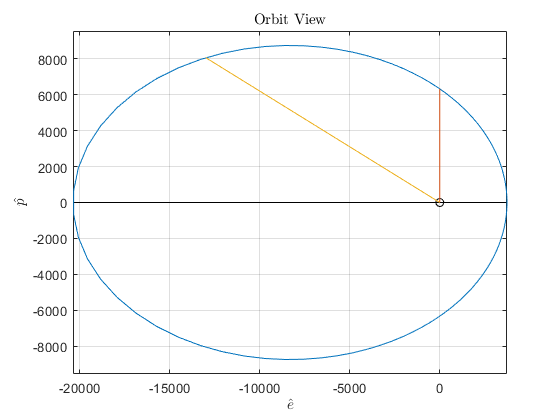

plot_orbit(e,p)
plot([0,0],[0,p])
plot([0,r1*cos(theta_1)],[0,r1*sin(theta_1)])

Ec = 2*atan(tand(45)*sqrt((1-e)/(1+e)))

Ec = 0.8091

rad2deg(Ec)

ans = 46.3587

tc_tp = sqrt(a^3/mu)*(Ec-e*sin(Ec))

tc_tp = 1.9816e+03

t1_tc = t1_tp-tc_tp

t1_tc = 6.5474e+03

r1_n = r1

r1_n = 1.5287e+04

v1_n = sqrt(mu/r1_n)

v1_n = 1.6738

gamma1_n = acos(sqrt(mu/r1_n)/v1_n)

gamma1_n = 0

deltaV1 = sqrt(v1^2+v1_n^2-2*v1*v1_n*cos(gamma1))

deltaV1 = 1.1189

beta1 = asin(v1_n/deltaV1*sin(gamma1))

beta1 = 1.4135

rad2deg(beta1)

ans = 80.9862

alpha1 = pi-beta1

alpha1 = 1.7281

rad2deg(alpha1)

ans = 99.0138

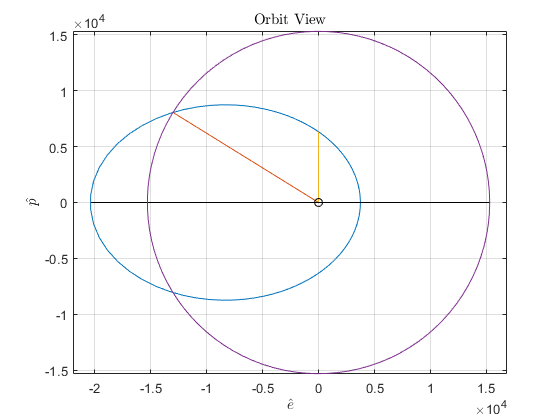

figure
plot_orbit(e,p)
plot([0,r1*cos(theta_1)],[0,r1*sin(theta_1)])
plot([0,0],[0,p])
plot_orbit(0,r1_n)

v1_vec = [-1.370216313540919, -0.4173318414722971, 0];
v1_n_vec = [-0.8808107697051142, -1.423302171925606, 0];
dv = v1_n_vec-v1_vec

dv =     0.4894   -1.0060         0


norm(dv)

ans = 1.1187

## Problem 2

clear;
R_Earth = 6378.1363;
mu = 398600.4415;
e = 0.4;
a = 4*R_Earth;
theta_a = deg2rad(135);
dV = 0.90;
alpha = deg2rad(45);

p = a*(1-e^2)

p = 2.1431e+04

r = p/(1+e*cos(theta_a))

r = 2.9883e+04

v = sqrt(2*mu/r-mu/a)

v = 3.3248

gamma = acos(sqrt(mu*p)/(r*v))

gamma = 0.3757

rad2deg(gamma)

ans = 21.5240

r_rth = [r 0 0]'

r_rth = 	1.0e+04 *

    2.9883
         0
         0


v_rth = v*[sin(gamma) cos(gamma) 0]' 

v_rth =     1.2198
    3.0929
         0


dv_rth = dV*[sin(alpha+gamma) cos(alpha+gamma) 0]'

dv_rth =     0.8255
    0.3585
         0


R = [cos(theta_a) -sin(theta_a) 0;sin(theta_a) cos(theta_a) 0;0 0 1]

R =    -0.7071   -0.7071         0
    0.7071   -0.7071         0
         0         0    1.0000


dv_eph = R*dv_rth

dv_eph =    -0.8372
    0.3302
         0


dv_vnb = dV*[cos(alpha) sin(alpha) 0]'

dv_vnb =     0.6364
    0.6364
         0


vn_rth = v_rth+dv_rth

vn_rth =     2.0453
    3.4514
         0


vn = norm(vn_rth)

vn = 4.0120


dgamma = asin(dV/vn*sin(0.75*pi))

dgamma = 0.1593

rad2deg(dgamma)

ans = 9.1271

gamma_n = gamma+dgamma

gamma_n = 0.5350

rad2deg(gamma_n)

ans = 30.6511

Ec = 2*atan(tan(theta_a/2)*sqrt((1-e)/(1+e)))

Ec = 2.0133

rad2deg(Ec)

ans = 115.3552

rn = r;
pn = (cos(gamma_n)*rn*vn)^2/mu

pn = 2.6687e+04

an = -mu/2/(vn^2/2-mu/rn)

an = 3.7668e+04

en = sqrt(1-pn/an)

en = 0.5399

hn = rn*vn*cos(gamma_n)

hn = 1.0314e+05

pn-hn^2/mu

ans = 0


period = 2*pi*sqrt(an^3/mu)

period = 7.2756e+04

epsilon = -mu/(2*an)

epsilon = -5.2910

theta_an = acos(pn/(rn*en)-1/en)

theta_an = 1.7702

rad2deg(theta_an)

ans = 101.4239


En = 2*atan(tan(theta_an/2)*sqrt((1-en)/(1+en)))

En = 1.1780

rad2deg(En)

ans = 67.4930

rn-an*(1-en*cos(En))

ans = 0


t_tp = sqrt(an^3/mu)*(En-en*sin(En))

t_tp = 7.8645e+03

rpn = an*(1-en)

rpn = 1.7330e+04

ran = an*(1+en)

ran = 5.8006e+04

domega = -theta_an+theta_a

domega = 0.5860

rad2deg(domega)

ans = 33.5761

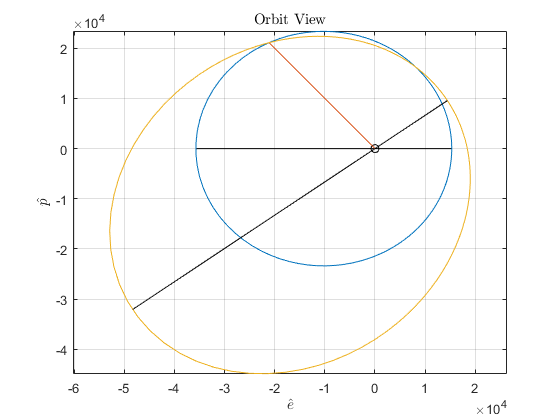

figure
plot_orbit(e,p)
plot([0,r*cos(theta_a)],[0,r*sin(theta_a)])

theta_vec = linspace(0,2*pi);
r_vec = pn./(1+en*cos(theta_vec));
x_vec = r_vec.*cos(theta_vec+domega);
y_vec = r_vec.*sin(theta_vec+domega);
plot(x_vec,y_vec)

plot([rpn, -ran]*cos(domega),[rpn, -ran]*sin(domega),'k')

## Problem 3

a = 3*R_Earth;
e = 0.6;
rpn = 2*R_Earth;
en = 0.4;
E = -pi/2;

r = a;
r_rth = [a 0 0]'

r_rth = 	1.0e+04 *

    1.9134
         0
         0


v = sqrt(2*mu/r - mu/a)

v = 4.5642

p = a*(1-e^2)

p = 1.2246e+04

gamma = -acos(sqrt(mu*p)/(r*v))

gamma = -0.6435

rad2deg(gamma)

ans = -36.8699

v_rth = v*[sin(gamma) cos(gamma) 0]'

v_rth =    -2.7385
    3.6513
         0


t_tp = sqrt(a^3/mu)*(E-e*sin(E))

t_tp = -4.0699e+03

theta_a = 2*atan(tan(E/2)*sqrt((1+e)/(1-e)))

theta_a = -2.2143

rad2deg(theta_a)

ans = -126.8699

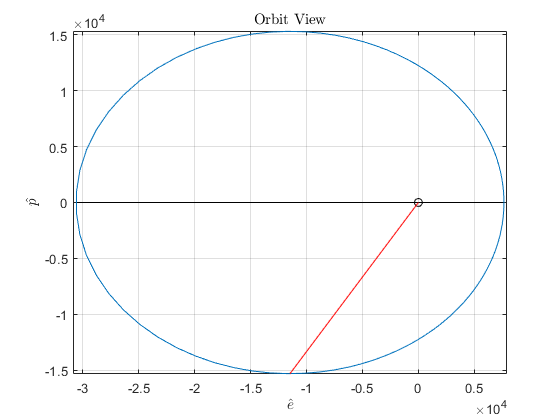

figure
plot_orbit(e,p)
plot([0,r*cos(theta_a)],[0,r*sin(theta_a)],'r-')

en = 0.4;
rn = r;
rpn = 2*R_Earth;
an = rpn/(1-en)

an = 2.1260e+04

pn = rpn*(1+en)

pn = 1.7859e+04

theta_an = acos((pn-rn)/(rn*en))

theta_an = 1.7382

rad2deg(theta_an)

ans = 99.5941


domega = theta_a-theta_an

domega = -3.9525

rad2deg(domega)

ans = -226.4640


vn = sqrt(2*mu/rn-mu/an)

vn = 4.7869

gamma_n = acos(sqrt(mu*pn)/(rn*vn))

gamma_n = 0.3998

rad2deg(gamma_n)

ans = 22.9078


dgamma = gamma_n-gamma

dgamma = 1.0433

rad2deg(dgamma)

ans = 59.7777


vn_rth = vn*[sin(gamma_n) cos(gamma_n) 0]'

vn_rth =     1.8633
    4.4094
         0


dv_rth = vn_rth-v_rth

dv_rth =     4.6018
    0.7581
         0


dv = norm(dv_rth)

dv = 4.6638

dv - sqrt(vn^2+v^2-2*vn*v*cos(dgamma))

ans = 0


beta = asin(vn/dv*sin(dgamma))

beta = 1.0906

rad2deg(beta)

ans = 62.4846

alpha = pi-beta

alpha = 2.0510

rad2deg(alpha)

ans = 117.5154


dv_vnb = dv*[cos(alpha) 0 sin(alpha)]'

dv_vnb =    -2.1546
         0
    4.1363


ran = 2*an-rpn

ran = 2.9765e+04

period = 2*pi*sqrt(an^3/mu)

period = 3.0851e+04

epsilon = -mu/(2*an)

epsilon = -9.3742

En = 2*atan(tan(theta_an/2)*sqrt((1-en)/(1+en)))

En = 1.3181

rad2deg(En)

ans = 75.5225


t_tp = sqrt(an^3/mu)*(En-e*sin(En))

t_tp = 3.6196e+03

(period-t_tp)/(3600)

ans = 7.5643

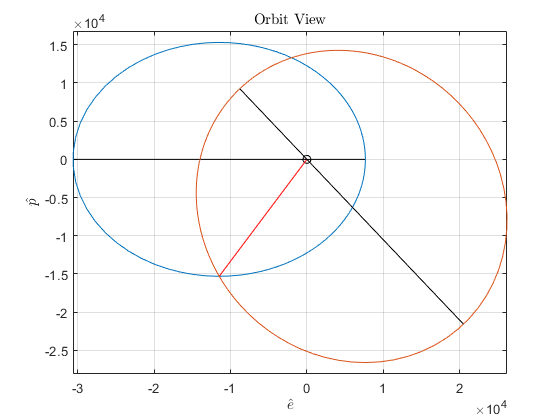

figure
plot_orbit(e,p)
plot([0,r*cos(theta_a)],[0,r*sin(theta_a)],'r-')

theta_vec = linspace(0,2*pi);
r_vec = pn./(1+en*cos(theta_vec));
x_vec = r_vec.*cos(theta_vec+domega);
y_vec = r_vec.*sin(theta_vec+domega);
plot(x_vec,y_vec)

plot([rpn, -ran]*cos(domega),[rpn, -ran]*sin(domega),'k')